# **IO3xx I/O Interface Extension (-21,-22,-24) Digital Loopback**

This example shows how to perform a loopback test using an IO3xx I/O interface extension, such as -21, -22 or -24. You can test the basic I/O interface extension by running this example, which is also used to demonstrate how the Speedgoat I/O Blockset informs you in case something is wrong in your configuration.

## Setup

### Prerequisites

You will require the following to run this example:

- A Speedgoat real-time target machine with one I/O module from the IO3xx family and an I/O interface extension installed

- A Speedgoat configuration file that supports an I/O interface extension

- A connector cable from the I/O modules to the terminal board

- A terminal board with jumper wires

### Test Setup

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect these pins with jumper wires. Note that this example will be suitable for almost all combinations of any Configurable I/O module with any of the supported I/O interface extensions. There are a few combinations—especially if you have a -22 I/O interface extension—where this mapping for the below specified I/O configuration is not possible. If so, you can simply connect any other combination of four DIO signals (input and output) on the I/O interface extension; however in this case, you will need to change the DIO channels in the model later.

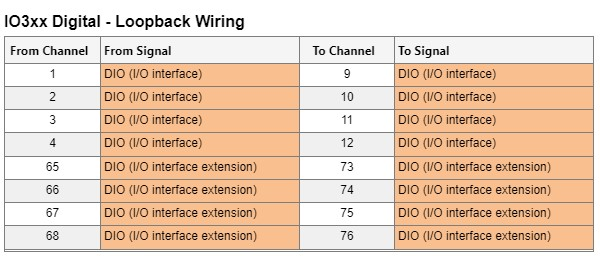

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_2x_DigitalLoopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities. For this example also make sure the I/O interface extension is enabled.

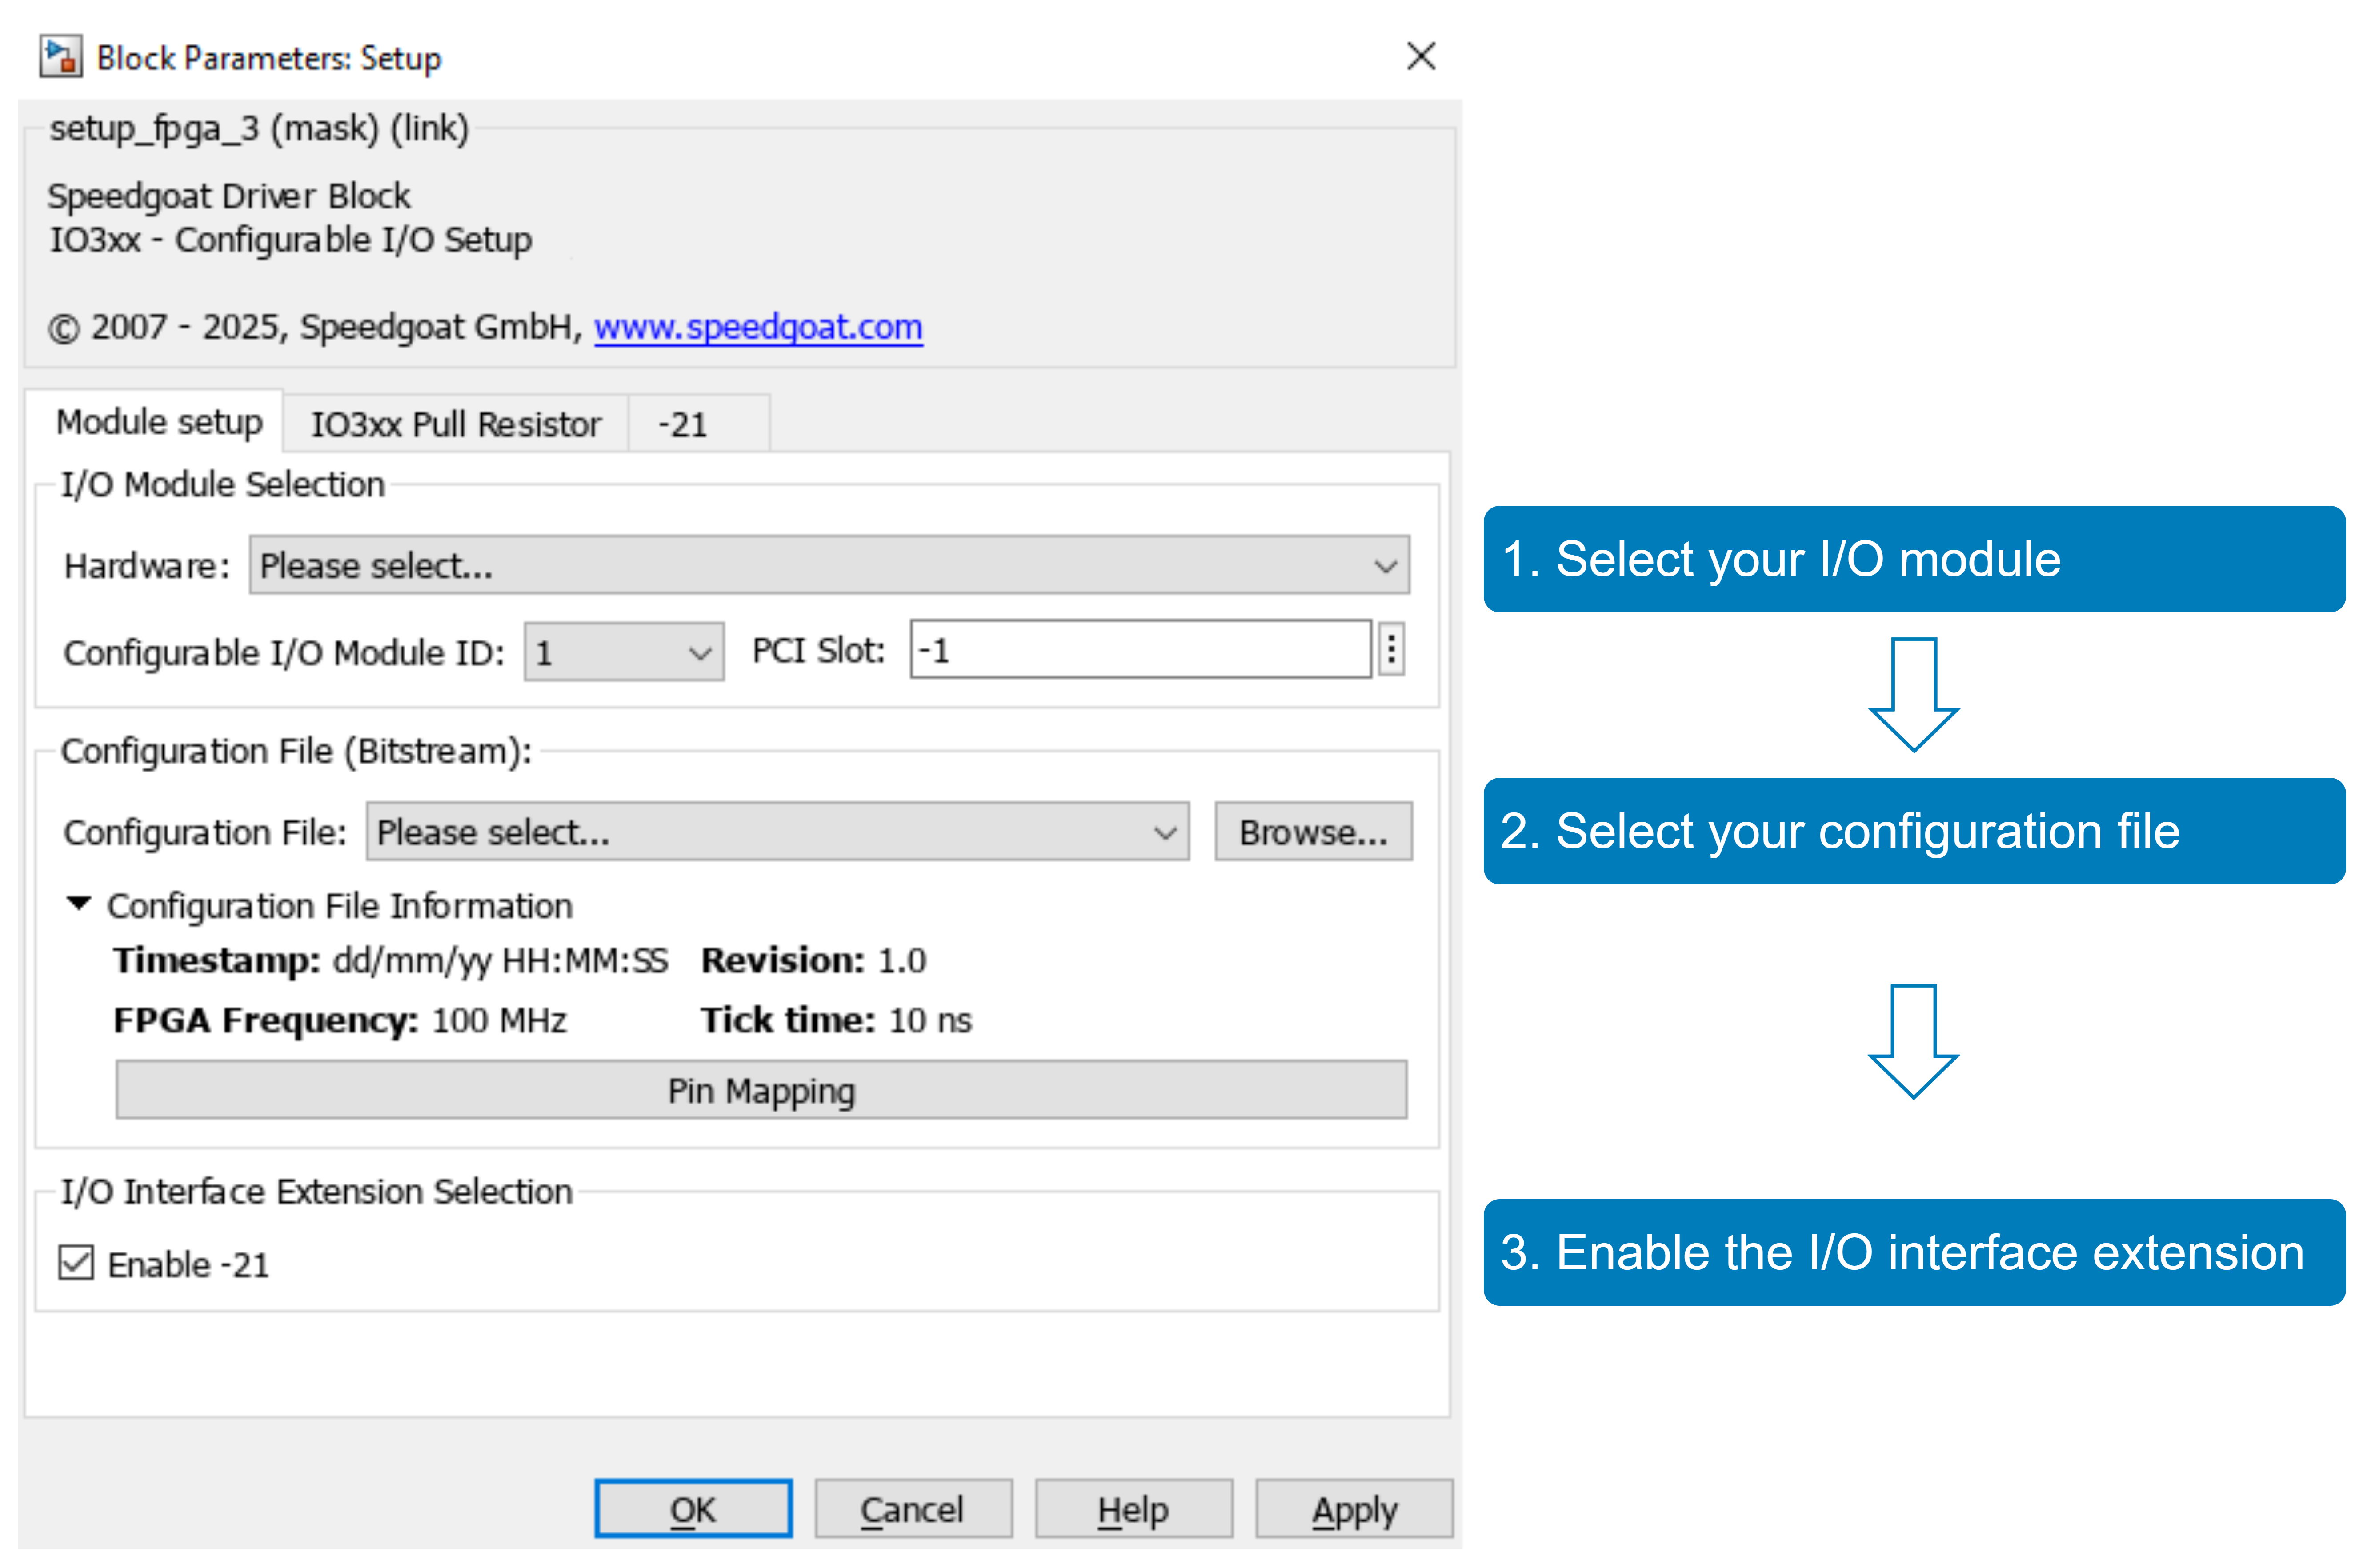

The information of your implemented I/O interface extension functionality is contained in the configuration file. If the selected configuration file doesn't support an I/O interface extension, the checkbox won't be visible.

To still run this example, it is possible to select DIO lines of the configurable I/O module itself.

### Model Description

In this model, digital outputs ch1–4 values are received by digital inputs ch9–12. These channels are located on the IO3xx module itself. Digital outputs ch65–68 are received by digital inputs ch73–76. These channels are located on the I/O interface extension.

Note that in case you did not enable the I/O interface extension in the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block, all I/O functionalities located on the I/O interface extension are turned off. If this is the case when using this example model, a warning will be shown in the MATLAB command window while modifying the Simulink model:

- *Warning: Following DI are located on disabled I/O interface extension:*

- *    - 73*

- *    - 74*

- *    - 75*

- *    - 76*

- *Warning: Following DO are located on disabled I/O interface extension:*

- *    - 65*

- *    - 66*

- *    - 67*

- *    - 68*

If you do a manual update of the Simulink model (using Ctrl+D), these warnings will be changed to an error message. If so, make sure to select the correct I/O interface extension in the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) driver block (see here).

The scope displays the received digital values on the Configurable I/O module and the received digital values on the I/O interface extension.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check the loopback is working as expected, open the Simulink scope that is connected to the Digital Input and Digital Output driver blocks. The scope must display the signals as shown below:

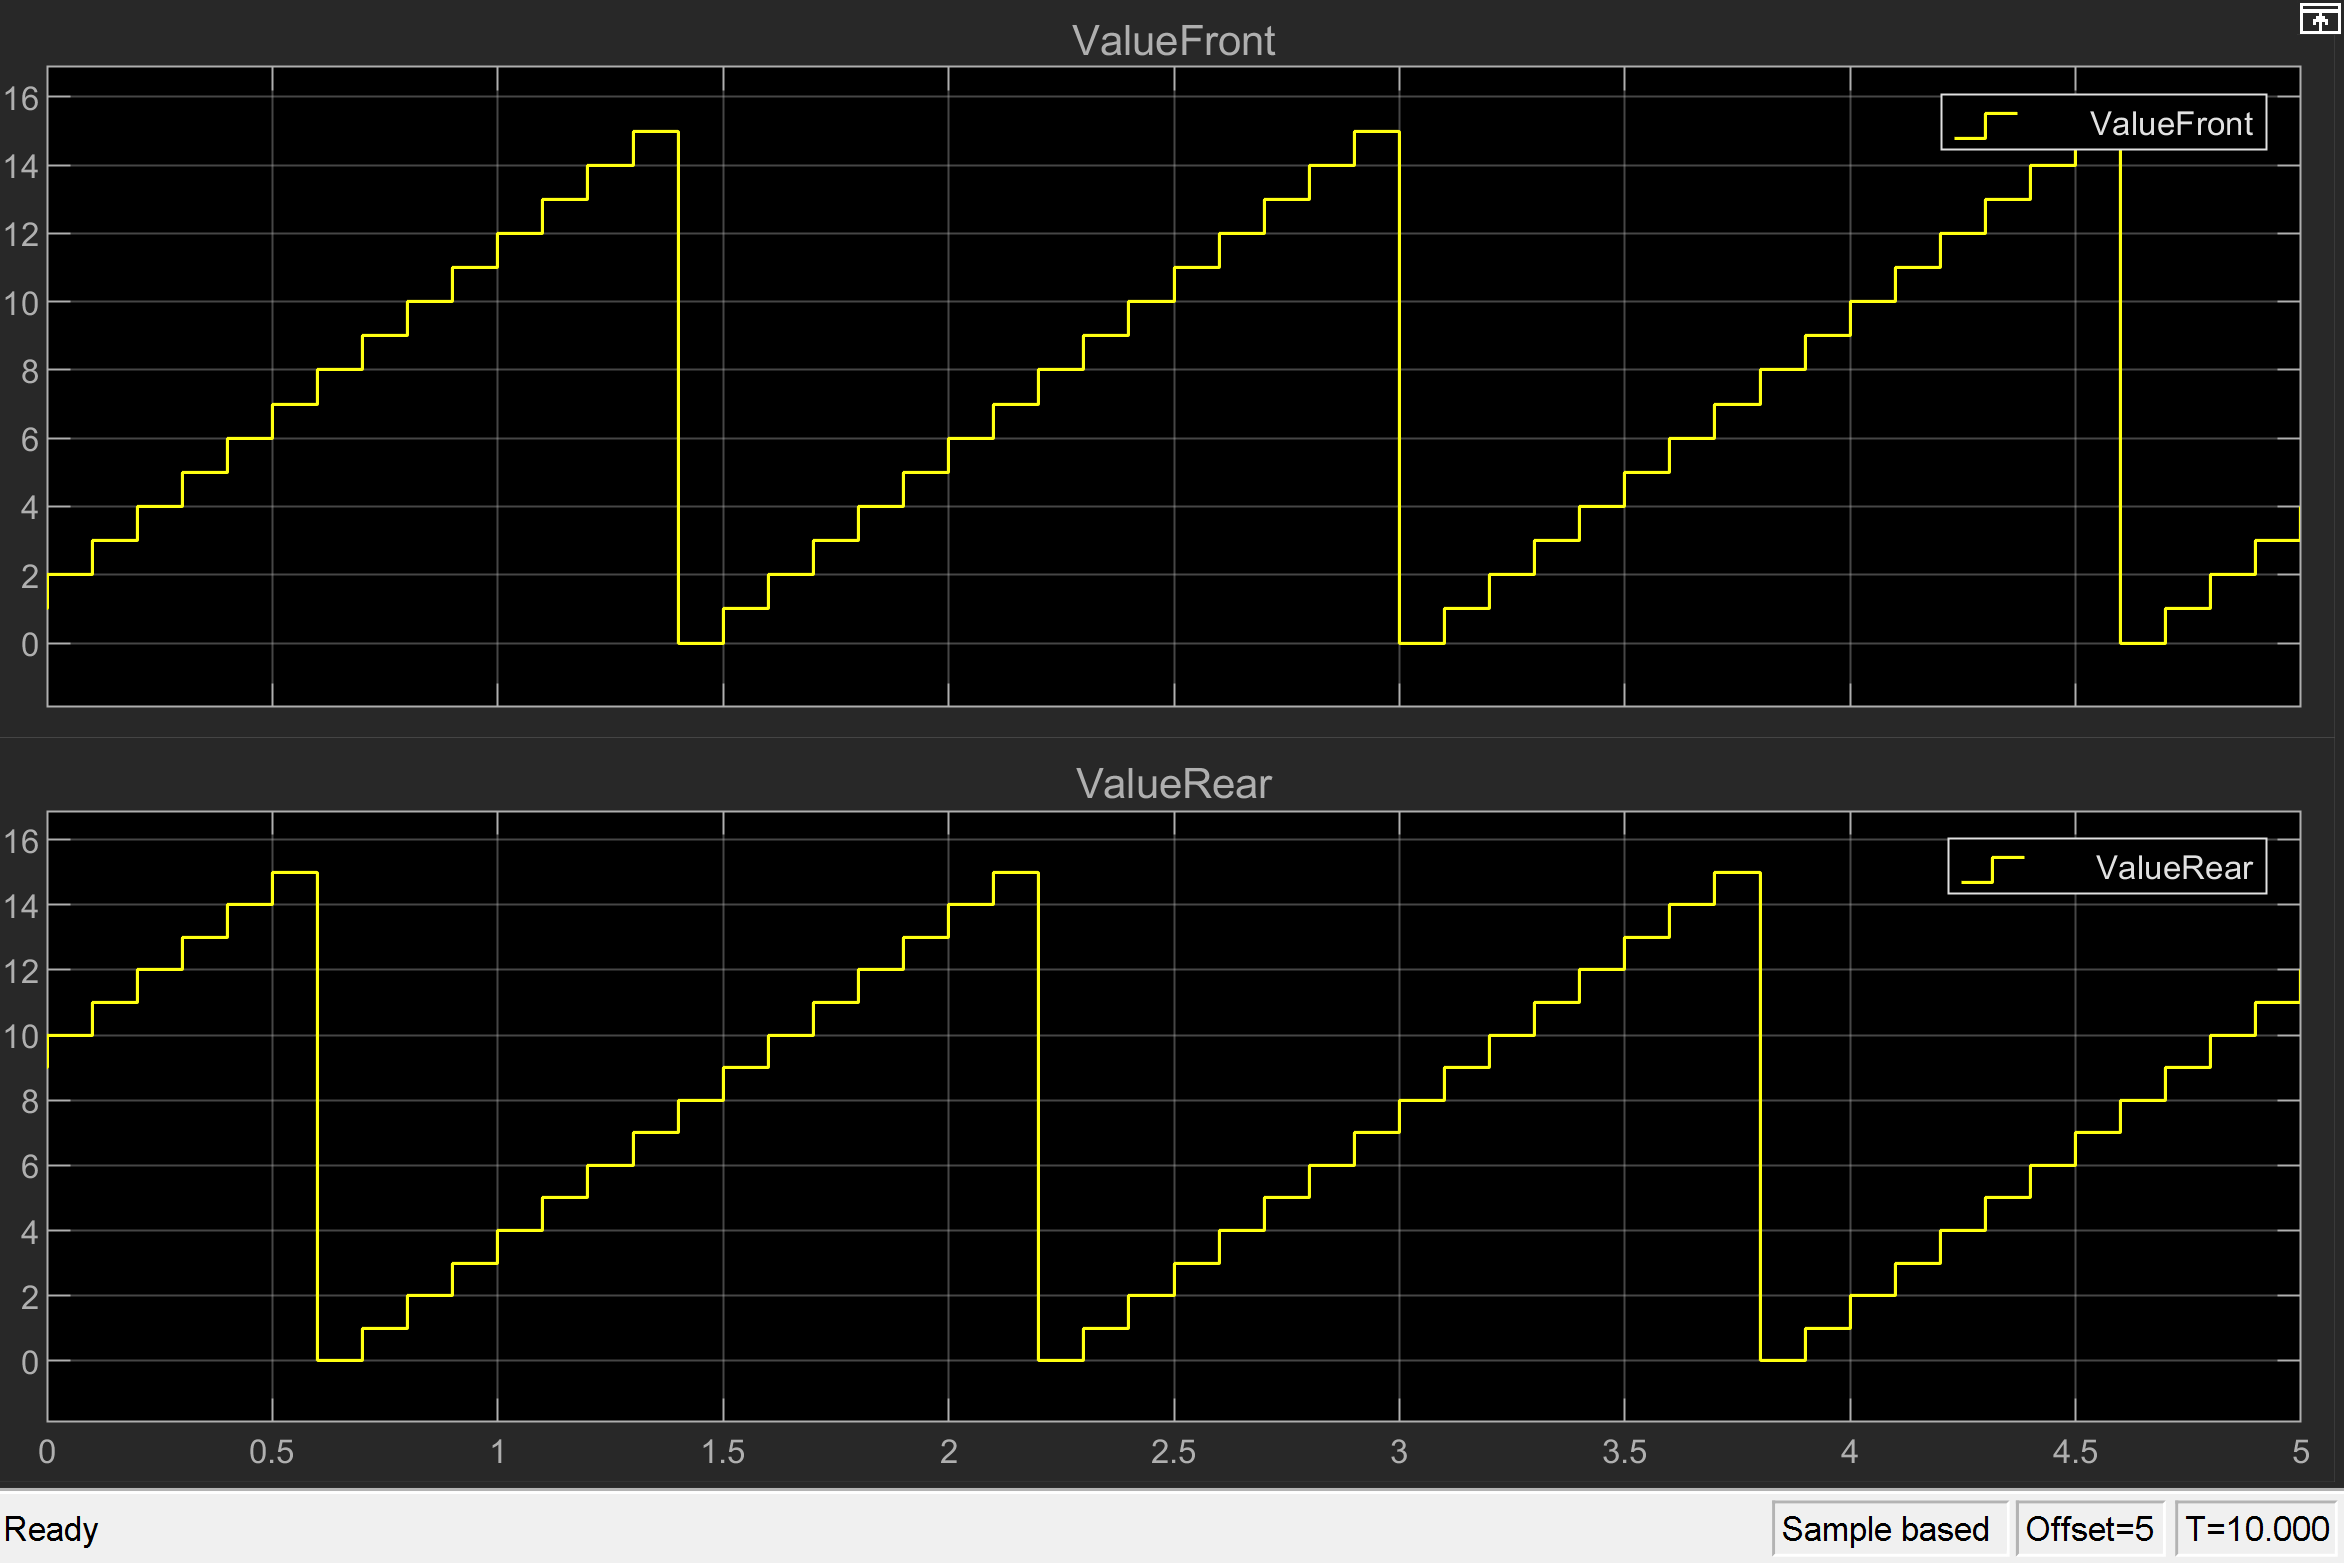

## Additional References

- [IO3xx I/O Interface Extensions](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io_interface_extensions)